# Does the Maxwell PDF function make sense?

T = 300.0; % k
m = 2.0;   % amu
vmax = 1.0e+4; % m/s

vs = linspace(0, vmax, 1000);
pdf = maxwell_pdf(vs, m, T);
figure
plot(vs, pdf);

f = @(v) maxwell_pdf(v, m, T)

f = function_handle with value:
    @(v)maxwell_pdf(v,m,T)


fprintf("Normalization: %.8g\n", integral(f, 0, vmax));

Normalization: 1


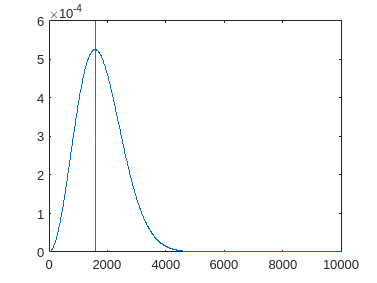


% Plot most probable speed
k = 1.380649e-23; 
hold on
xline(sqrt(2 * k * 300 / (m*1.6605e-27)))
hold off

## Try out the random number generator

% SLOW, but it works!
N = 10^5;
dv = 1.0;

tic
dist_points = maxwell_distribution(N, m, T, dv, vmax);
toc

Elapsed time is 4.067913 seconds.


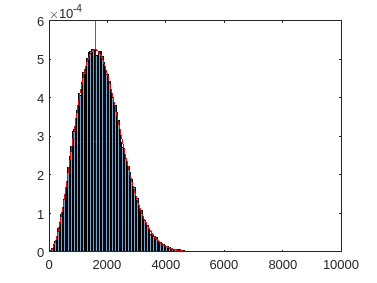


figure;
histogram(dist_points, 'Normalization', 'pdf');
xlim([0, vmax])

hold on
xline(sqrt(2 * k * 300 / (m*1.6605e-27)))
vs = linspace(0, vmax, 1000);
pdf = maxwell_pdf(vs, m, T);
plot(vs, pdf, 'r');
hold off

## Try out the general version

N = 10^5;
dv = 1.0;

desired_pdf = @(v) maxwell_pdf(v, m, T);

tic
dist_points = general_distribution(N, dv, vmax, desired_pdf);

'general_distribution' is not found in the current folder or on the MATLAB path, but exists in:
    /home/dknapp/ownCloud - Daniel Knapp@vu.data.surfsara.nl/dknapp/002_ion_trap/06_Examples/010_Paul_trap_with_ion_injection
    /home/dknapp/ownCloud - Daniel Knapp@vu.data.surfsara.nl/dknapp/002_ion_trap/06_Examples/001_basic_Paul_trap

Change the MATLAB current folder or add its folder to the MATLAB path.

toc

figure;
histogram(dist_points, 'Normalization', 'pdf');
xlim([0, vmax])

hold on
xline(sqrt(2 * k * 300 / (m*1.6605e-27)))
vs = linspace(0, vmax, 1000);
pdf = maxwell_pdf(vs, m, T);
plot(vs, pdf, 'r');
hold off